clear;
dim_num = 4;
tag_num = 100;
sample_num = 78;
fold_name_list = ["embeddings_length4_f12_2_lo_1_0.94/",...
                "embeddings_length4_f12_4_lo_1_0.95/",...
                "embeddings_length4_f12_8_lo_1_0.96/",...
                "embeddings_length4_f12_8_lo_2_0.98/",...
                "embeddings_length4_f12_8_lo_3_0.99/"];
tag_id = 2;
for i = 5
    figure('OuterPosition',[0 0 600 150]);
    file_name = strcat(fold_name_list(i),"all_data.txt");
    all_data = dlmread(file_name,','); 
    for dim_id = 1:dim_num
        current_dim = all_data(tag_id:tag_id+sample_num-1, dim_id);
        pd = fitdist(current_dim,'Normal');
        fprintf('均值 = %f\n', pd.mu);
        fprintf('标准差 = %f\n', pd.sigma);
        subplot(1,dim_num,dim_id);
        histogram(current_dim,'Normalization',"pdf","NumBins",10,'EdgeColor',"none",'FaceColor',[130 176 210]/255);
        x = linspace(min(current_dim), max(current_dim), 1000);
        y = pdf(pd, x);
        hold on;
        plot(x, y, 'LineWidth', 3,'Color',[250 127 111]/255);
        hold off;
        xlabel(strcat("Dimension ",num2str(dim_id)));
        if dim_id == 1
            ylabel("PDF");
        end
        set(gca, 'FontSize', 16, 'FontName','Arial');
    end
end

均值 = 0.266309


标准差 = 0.075269


均值 = 0.470220


标准差 = 0.053562


均值 = -0.328378


标准差 = 0.080816


均值 = 0.754675


标准差 = 0.126244


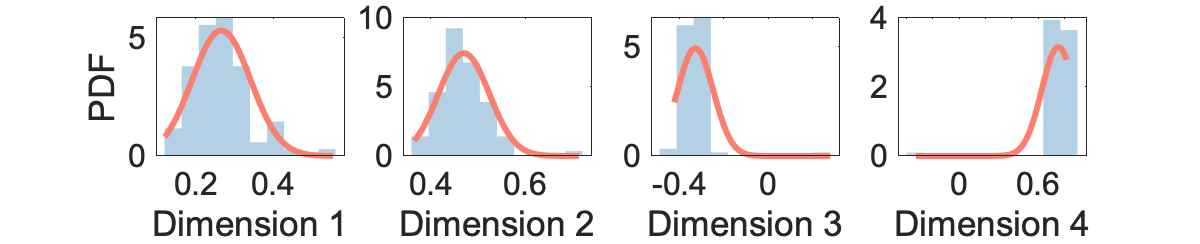

exportgraphics(gcf,"./single_tag_distribution.pdf");


all_data = dlmread('all_data_3.txt', ',');
dim_num = 4;
tag_num = 100;
sample_num = 78;
barWidth = 0.7;
dx = [0.05293218,0.05327797,0.04759572,0.04964485];
figure('OuterPosition',[0,0,600,150]);
final_entropy = 0;
for dim_id = 1:dim_num
    subplot(1,4,dim_id);
    counts = floor(2/dx(dim_id)/2.3548)
    [distribution_estimate, edges] = histcounts(all_data(:,dim_id), counts);
    distribution_estimate = distribution_estimate/7800;
    bar(linspace(-1,1,counts),distribution_estimate,barWidth,'FaceColor', [130 176 210]/255,'EdgeColor', 'none');
    ylim([0,0.2]);
    entropy = -sum(distribution_estimate.*log2(distribution_estimate));
    final_entropy = final_entropy + entropy;
    xlabel("Dimension " + num2str(dim_id));
    if dim_id == 1
        ylabel("PDF");
    end
    set(gca, 'FontSize', 16, 'FontName','Arial');
end

counts = 16

counts = 15

counts = 17

counts = 17

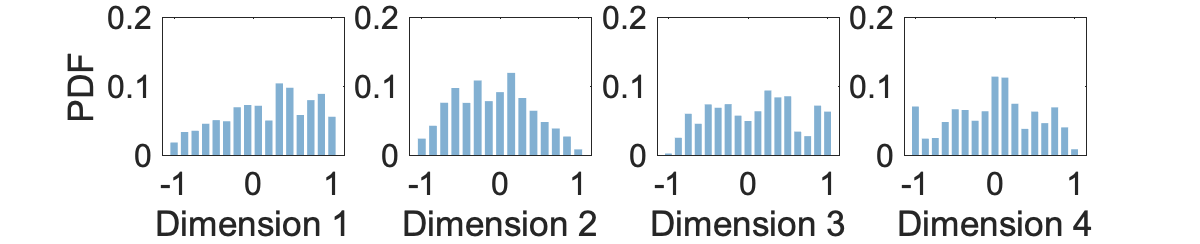

exportgraphics(gcf,"./all_tag_distributions.pdf");

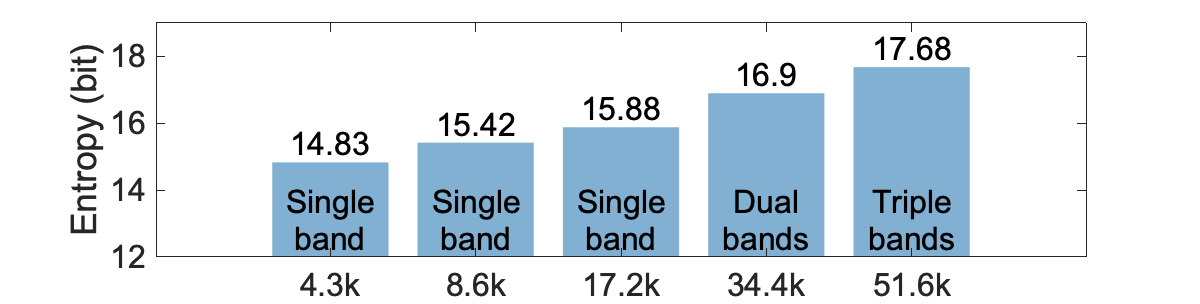

% entropy v.s. frequencies
entropy = [14.83, 15.42, 15.88, 16.90, 17.68];
figure('OuterPosition',[0,0,600,180]);
% categories = {'4320', '8640', '17280'};
categories = {'4.3k', '8.6k', '17.2k','34.4k','51.6k'};

barWidth = 0.8;
b = bar(entropy(1:5),barWidth,'FaceColor', [130 176 210]/255,'EdgeColor', 'none');

barPositions = b.XData;
barHeights = b.YData;

for i = 1:length(entropy(1:5))
    text(barPositions(i), barHeights(i), num2str(barHeights(i)), ...
         'HorizontalAlignment', 'center', ...
         'VerticalAlignment', 'bottom','FontSize',16,'FontName','Arial');
end

for i = 1:length(entropy(1:3))
    text(barPositions(i), 12, {'Single', 'band'}, ...
         'HorizontalAlignment', 'center', ...
         'VerticalAlignment', 'bottom','FontSize',16,'FontName','Arial');
end

text(barPositions(4), 12, {'Dual', 'bands'}, ...
         'HorizontalAlignment', 'center', ...
         'VerticalAlignment', 'bottom','FontSize',16,'FontName','Arial');

text(barPositions(5), 12, {'Triple', 'bands'}, ...
         'HorizontalAlignment', 'center', ...
         'VerticalAlignment', 'bottom','FontSize',16,'FontName','Arial');


% 设置 x 轴标签

ylim([12 19]);

% 添加标题和标签
% xlabel('Input categories');
ylabel('Entropy (bit)');
set(gca, 'XTickLabel', categories,'FontSize', 16, 'FontName','Arial');


exportgraphics(gcf,"./entropy_frequency.pdf")

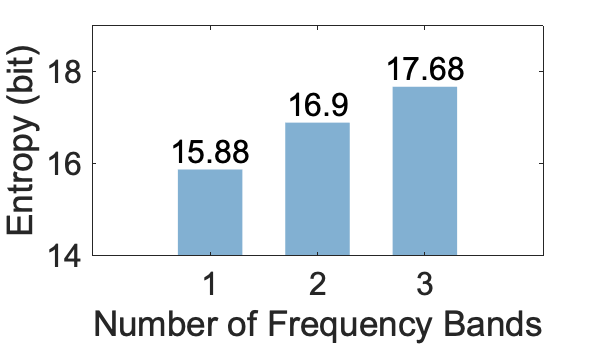

figure('OuterPosition',[0,0,300,200]);
categories = {'1', '2', '3'};

barWidth = 0.6;
b = bar(entropy(3:5),barWidth,'FaceColor', [130 176 210]/255,'EdgeColor', 'none');


barPositions = b.XData;
barHeights = b.YData;

for i = 1:length(entropy(1:3))
    text(barPositions(i), barHeights(i), num2str(barHeights(i)), ...
         'HorizontalAlignment', 'center', ...
         'VerticalAlignment', 'bottom','FontSize',16,'FontName','Arial');
end

% 设置 x 轴标签
set(gca, 'XTickLabel', categories,'FontSize', 16, 'FontName','Arial');
ylim([14 19]);
% 添加标题和标签
xlabel('Number of Frequency Bands');
ylabel('Entropy (bit)');
exportgraphics(gcf,"./entropy_band.pdf");

counts = 16

counts = 15

counts = 17

counts = 17

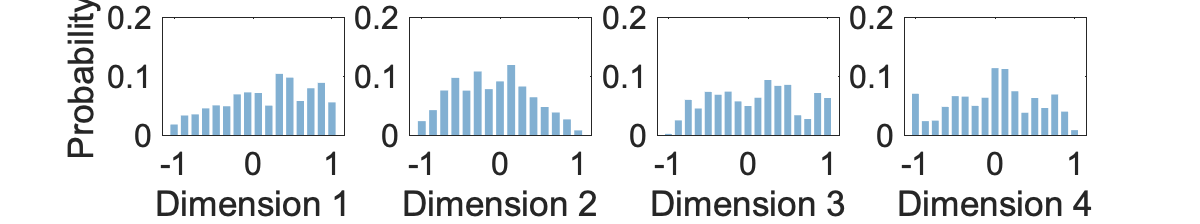

% extraText = "1: 1025 - 1050 MHz\n2: 950 - 975 MHz\n3:850 - 875 MHz";
% text(1, 10, extraText, 'FontSize', 16, 'FontName','Arial', 'HorizontalAlignment', 'center');

dim_id = 1;
data_norm = (all_data(:,dim_id) + 1)/2;


% 定义均匀分布的CDF函数
uniformCDF = [(0:0.001:1)', (0:0.001:1)'];

% 使用kstest
[h, p] = kstest(data_norm, 'CDF', uniformCDF);

if h == 0
    disp('Do not reject the null hypothesis at the 5% significance level.');
else
    disp('Reject the null hypothesis at the 5% significance level.');
end

Reject the null hypothesis at the 5% significance level.
